## Fit bioluminescence data of clock-SCG model

Load experimental data

clear;clc
biolu_data_CT6 = importdata('biolu_data_CT6.txt');
biolu_data_CT18 = importdata('biolu_data_CT18.txt');

biolu_data_CT6(:, 1) = biolu_data_CT6(:, 1) - 48 + 500;
biolu_data_CT18(:, 1) = biolu_data_CT18(:, 1) - 24 + 500;

Optimize using fminsearch

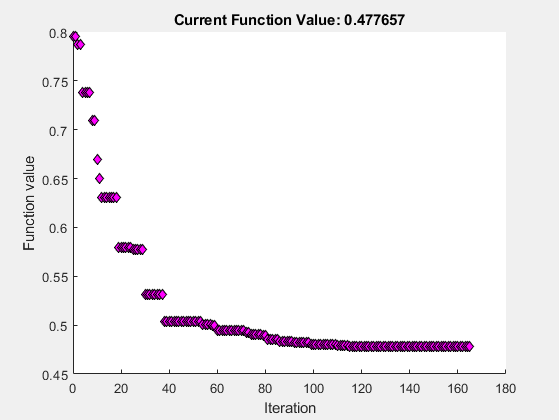

Optimization terminated prematurely by user.


par_base = importdata('par_scg_clock_base.txt');
par_base = par_base.data;

FitFcn = @(par_fit)Fit_err_clock(biolu_data_CT6, biolu_data_CT18, par_fit);

options_fmin = optimset('PlotFcns',@optimplotfval);
[p, fminres] = fminsearch(FitFcn, par_base, options_fmin);

disp(p');

  Columns 1 through 4

      0.000174425829898784         0.170457001565395        0.0224049260216482          623029.761301885

  Columns 5 through 6

         0.129909994089452          18.9669815362939



format long g;
disp(p');

  Columns 1 through 4

      0.000174425829898784         0.170457001565395        0.0224049260216482          623029.761301885

  Columns 5 through 6

         0.129909994089452          18.9669815362939



Plot simmulation and data

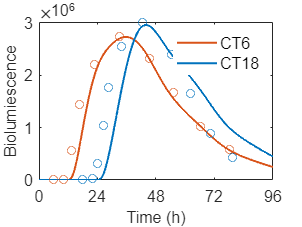

% load parameters
par_scg = importdata('par_scg_clock_base.txt');
par_scg = par_scg.data;

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_clock+4, 1);
y0(n_clock+1) = 1;
y0(n_clock+4) = 0;

tmax = 1000;
tspan = 0:0.1:tmax;

t_V = zeros(4, 1);  % CT0, CT6, CT12, CT18
for i = 1:4
    t_V(i) = 500 + 6 * (i - 1);
end

y = zeros(length(tspan), n_clock+4, 5);
for i = 1:4
    [~, y(:, :, i)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V(i));
end
y = real(y);

% Plot bioluminescence (B)
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
% color4 = [142 207 201; 250 127 111; 255 190 122; 130 176 210] ./ 255;
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = [2 4]
    plot(tspan, y(:, n_clock+4, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end

scatter(biolu_data_CT6(:, 1), biolu_data_CT6(:, 2), [], color4(2, :));
scatter(biolu_data_CT18(:, 1), biolu_data_CT18(:, 2), [], color4(4, :));

xlim([500 596]);
xticks(500:24:596);
xticklabels({'0', '24', '48', '72', '96'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Biolumiescence','Fontsize',12, 'FontName', 'Arial');
legend('CT6', 'CT18', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

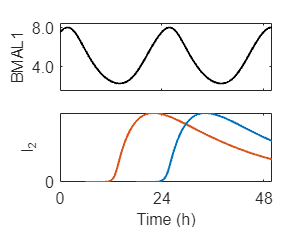

% Plot BMAL1 and phases of infection and peak time of I2

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.6 0.7 0.3]);
plot(tspan, y(:, 10, 2), 'k', 'LineWidth', 1.5);
xlim([500 550]);
xticks([500 524 548]);
xticklabels({});
ylim([1.5 8.5]);
yticks([4 8]);
yticklabels({'4.0', '8.0'});
ylabel('BMAL1','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.2 0.2 0.7 0.3]);
for i = [2 4]
    plot(tspan((t_V(i)*10+1):end), y((t_V(i)*10+1):end, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([500 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
% ylim([-0.02 0.8]);
yticks([0 0.2]);
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
hold off;

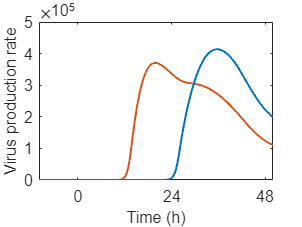

% plot K_BMAL1_V / (K_BMAL1_V + BMAL1) * p_V * I2
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
color4 = [0.9290 0.6940 0.1250; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0 0.4470 0.7410];
for i = [2 4]
    plot(tspan, par_scg(6)./(par_scg(6)+y(:, 10, i)).*par_scg(4).*y(:, n_clock+3, i), 'LineWidth', 1.5, 'Color', color4(i, :));
end
xlim([490 550]);
xticks([500 524 548]);
xticklabels({'0', '24', '48'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial'); ylabel('Virus production rate','Fontsize',12, 'FontName', 'Arial');
hold off;